# HW: Multiple Comparisons 

First, simulate multiple (say, 1000) t-tests comparing two samples with equal means and standard deviations, and save the p-values. Obviously, at p<0.05 we expect that ~5% of the simulations to yield a "statistically significant" result (of rejecting the NULL hypothesis that the samples come from distributions with equal means).

Using ChatGTP: 

- I first asked it to generate the p-values, originally the proportion of significant results was "0.036" so I noticed that the random samples it was generating did not have the same mean, so I asked it to modify that

- Then, to help with the visualization, I asked it to plot a histogram with the frquency of occurence over the p-values and highlight the ones that were under 0.05

Results: I finally got the expected outcome that 5% of the simulations gave a significant result 

% Set the parameters
numSimulations = 1000;  % Number of simulations
sampleSize = 50;        % Sample size for each group
alpha = 0.05;           % Significance level

% Initialize an array to store p-values
pValues = zeros(numSimulations, 1);

% Perform the simulations and store p-values
for i = 1:numSimulations
    % Generate two random samples with the same mean and standard deviation
    meanValue = randn(1);  % Generate a random mean
    stdDev = randn(1);     % Generate a random standard deviation
    sample1 = meanValue + stdDev * randn(sampleSize, 1);
    sample2 = meanValue + stdDev * randn(sampleSize, 1);
    
    % Perform a two-sample t-test
    [~, p] = ttest2(sample1, sample2);
    
    % Store the p-value
    pValues(i) = p;
end

% Display the first 10 p-values (you can change the number as desired)
disp('First 10 p-values:');

First 10 p-values:


disp(pValues(1:10));

    0.7222
    0.6241
    0.3091
    0.2650
    0.0497
    0.8918
    0.7138
    0.2910
    0.2608
    0.0388




% Calculate the proportion of significant results (p < 0.05)
numSignificant = sum(pValues < alpha);
proportionSignificant = numSignificant / numSimulations;

fprintf('Proportion of significant results (p < %.2f): %.4f\n', alpha, proportionSignificant);

Proportion of significant results (p < 0.05): 0.0560


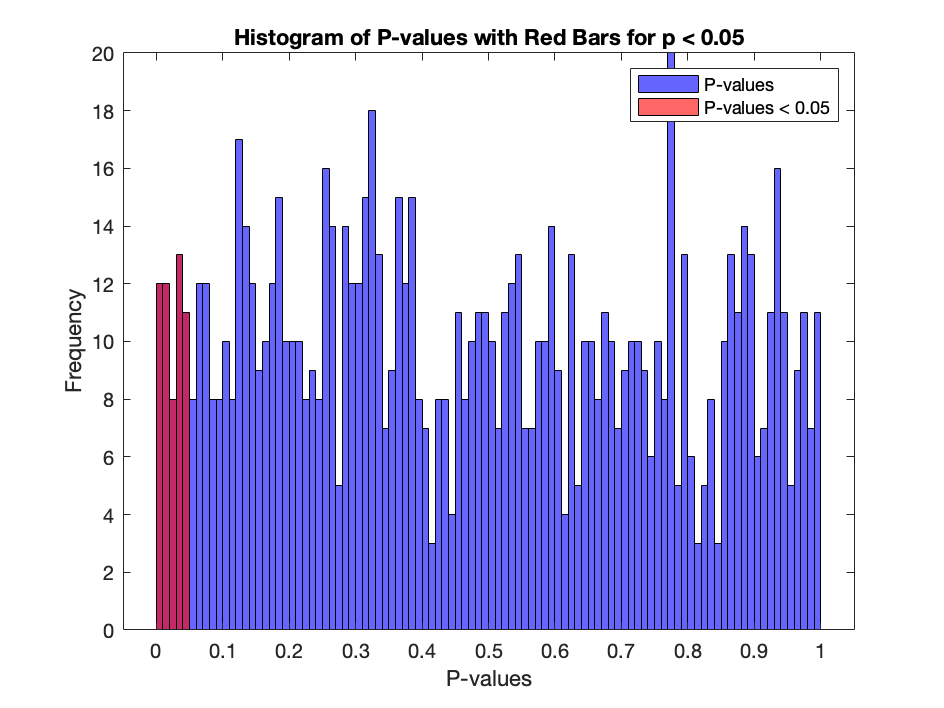


% Create a histogram plot of p-values with red bars for p-values < 0.05
figure;
histogram(pValues, 'BinWidth', 0.01, 'FaceColor', 'b');
hold on;

% Identify and highlight p-values < 0.05 with red bars
significantIndices = pValues < alpha;
histogram(pValues(significantIndices), 'BinWidth', 0.01, 'FaceColor', 'r');

xlabel('P-values');
ylabel('Frequency');
title('Histogram of P-values with Red Bars for p < 0.05');
legend('P-values', 'P-values < 0.05');
hold off;

Second, once you have the simulated p-values, apply both methods to address the multiple comparisons problem.

First: Applying the Bonferroni correction

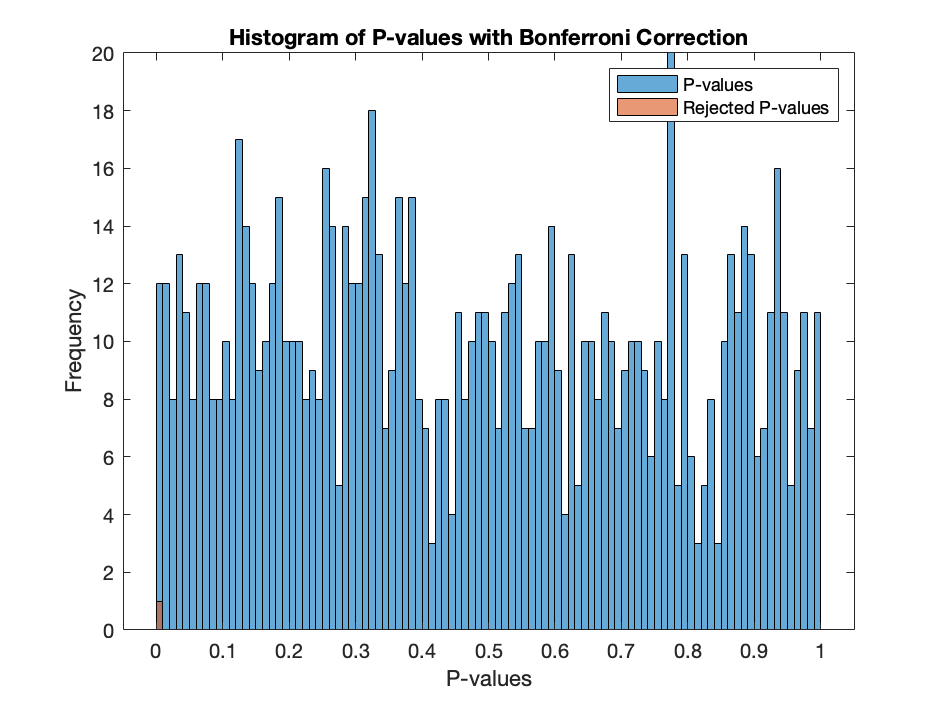


% Calculate Bonferroni corrected alpha
alphaBonferroni = alpha / numSimulations;

% Identify the p-values that can be rejected based on Bonferroni correction
rejectedPValues = pValues < alphaBonferroni;

% Create a histogram plot of p-values with frequency on the y-axis
figure;
histogram(pValues, 'BinWidth', 0.01);
hold on;
histogram(pValues(rejectedPValues), 'BinWidth', 0.01);
xlabel('P-values');
ylabel('Frequency');
title('Histogram of P-values with Bonferroni Correction');
legend('P-values', 'Rejected P-values');
hold off;


% Calculate the proportion of significant results after Bonferroni correction
numSignificantBonferroni = sum(rejectedPValues);
proportionSignificantBonferroni = numSignificantBonferroni / numSimulations;

fprintf('Proportion of significant results (Bonferroni corrected): %.4f\n', proportionSignificantBonferroni);

Proportion of significant results (Bonferroni corrected): 0.0010


Second: Applying the Benjamini–Hochberg procedure

% Set the parameters
numSimulations = 1000;  % Number of simulations
sampleSize = 50;        % Sample size for each group
alpha = 0.05;           % Significance level

% Initialize an array to store p-values
pValues = zeros(numSimulations, 1);

% Perform the simulations and store p-values
for i = 1:numSimulations
    % Generate two random samples with the same mean and standard deviation
    meanValue = randn(1);  % Generate a random mean
    stdDev = randn(1);     % Generate a random standard deviation
    sample1 = meanValue + stdDev * randn(sampleSize, 1);
    sample2 = meanValue + stdDev * randn(sampleSize, 1);
    
    % Perform a two-sample t-test
    [~, p] = ttest2(sample1, sample2);
    
    % Store the p-value
    pValues(i) = p;
end
% Sort the p-values in ascending order and get their rankings
[sortedPValues, pValueRankings] = sort(pValues);

% Calculate the Benjamini-Hochberg critical values
m = numSimulations;
bhCriticalValues = (1:m) / m * alpha;

% Create a table with rankings, original p-values, and BH critical values
BHTable = table(pValueRankings, sortedPValues, bhCriticalValues', 'VariableNames', {'Ranking', 'OriginalPValue', 'BH_CriticalValue'});

% Sort the table by Ranking column
BHTableSorted = sortrows(BHTable, 'Ranking');

% Display the sorted table
disp(BHTableSorted);% Display the sorted table

    Ranking    OriginalPValue    BH_CriticalValue
    _______    ______________    ________________

        1           0.60261          0.02995     
        2           0.41748          0.02105     
        3          0.017066          0.00065     
        4           0.63886          0.03175     
        5           0.31263           0.0154     
        6           0.55923          0.02785     
        7          0.092942          0.00325     
        8           0.44413           0.0229     
        9           0.44366          0.02285     
       10           0.78751          0.03945     
       11          0.083188           0.0029     
       12           0.28937          0.01365     
       13           0.93682           0.0467     
       14           0.48234           0.0242     
       15           0.90925            0.045     
       16           0.72206           0.0366   

disp(BHTableSorted);

    Ranking    OriginalPValue    BH_CriticalValue
    _______    ______________    ________________

        1           0.60261          0.02995     
        2           0.41748          0.02105     
        3          0.017066          0.00065     
        4           0.63886          0.03175     
        5           0.31263           0.0154     
        6           0.55923          0.02785     
        7          0.092942          0.00325     
        8           0.44413           0.0229     
        9           0.44366          0.02285     
       10           0.78751          0.03945     
       11          0.083188           0.0029     
       12           0.28937          0.01365     
       13           0.93682           0.0467     
       14           0.48234           0.0242     
       15           0.90925            0.045     
       16           0.72206           0.0366   

% Initialize variables
k = 0;
numSignificant = 0;

% Iterate through sorted p-values and corresponding critical values
for i = 1:numSimulations
    if sortedPValues(i) < bhCriticalValues(i)
        k = i;
        numSignificant = numSignificant + 1;
    else
        break;  % Stop when the condition is no longer met
    end
end

% Reject null hypothesis for all p-values ranked before k
rejectedPValues = pValueRankings <= k;

% Display the proportion of significant results
proportionSignificant = numSignificant / numSimulations;

fprintf('Proportion of significant results: %.4f\n', proportionSignificant);

Proportion of significant results: 0.0000



% % Display the sorted table
% disp(BHTableSorted);
% % Find the largest rank (k) where p-value < critical value
% k = find(sortedPValues < bhCriticalValues', 1, 'last');
% 
% % Reject null hypothesis for all p-values ranked before k
% rejectedPValues = pValueRankings <= k;
% 
% % Display the proportion of significant results
% proportionSignificant = sum(rejectedPValues) / numSimulations;
% 
% fprintf('Proportion of significant results: %.4f\n', proportionSignificant);


Third, set the sample 1 and sample 2 means to be 1 and 2 respectively, and re-run the exercise. What do you notice? What if you make the difference between means even greater?

% Set the parameters
numSimulations = 1000;  % Number of simulations
sampleSize = 50;        % Sample size for each group
alpha = 0.05;           % Significance level

% Initialize an array to store p-values
pValues_new = zeros(numSimulations, 1);

% Perform the simulations and store p-values
for i = 1:numSimulations
    % Generate two random samples with the means as 1 and 2
    sample1 = 1 + stdDev * randn(sampleSize, 1);
    sample2 = 2 + stdDev * randn(sampleSize, 1);
    
    % Perform a two-sample t-test
    [~, p] = ttest2(sample1, sample2);
    
    % Store the p-value
    pValues_new(i) = p;
end
 

%First: Applying the Bonferroni correction

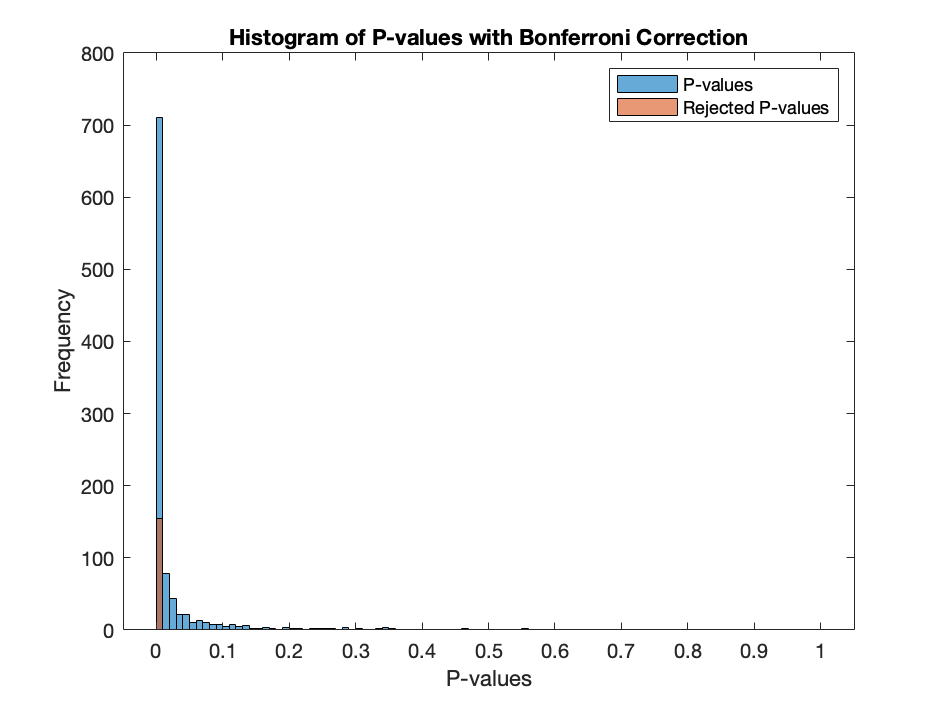

% Calculate Bonferroni corrected alpha
alphaBonferroni = alpha / numSimulations;

% Identify the p-values that can be rejected based on Bonferroni correction
rejectedPValues_new = pValues_new < alphaBonferroni;

% Create a histogram plot of p-values with frequency on the y-axis
figure;
histogram(pValues_new, 'BinWidth', 0.01);
hold on;
histogram(pValues_new(rejectedPValues_new), 'BinWidth', 0.01);
xlabel('P-values');
ylabel('Frequency');
title('Histogram of P-values with Bonferroni Correction');
legend('P-values', 'Rejected P-values');
hold off;


% Calculate the proportion of significant results after Bonferroni correction
numSignificantBonferroni_new = sum(rejectedPValues_new);
proportionSignificantBonferroni_new = numSignificantBonferroni_new / numSimulations;

fprintf('Proportion of significant results (Bonferroni corrected): %.4f\n', proportionSignificantBonferroni_new);

Proportion of significant results (Bonferroni corrected): 0.1540


Second: Applying the Benjamini–Hochberg procedure

% Sort the p-values in ascending order and get their rankings
[sortedPValues_new, pValueRankings_new] = sort(pValues_new);

% Calculate the Benjamini-Hochberg critical values
m = numSimulations;
bhCriticalValues_new = (1:m) / m * alpha;

% Create a table with rankings, original p-values, and BH critical values
BHTable_new = table(pValueRankings_new, sortedPValues_new, bhCriticalValues_new', 'VariableNames', {'Ranking', 'OriginalPValue', 'BH_CriticalValue'});

% Sort the table by Ranking column
BHTableSorted_new = sortrows(BHTable_new, 'Ranking');

% Display the sorted table
disp(BHTableSorted_new);

    Ranking    OriginalPValue    BH_CriticalValue
    _______    ______________    ________________

        1         0.0034681          0.02775     
        2          0.014312          0.03725     
        3         0.0005163          0.01735     
        4            0.1351           0.0472     
        5           0.07264            0.045     
        6          0.094152            0.046     
        7          0.019683          0.03935     
        8        3.2876e-06          0.00255     
        9        2.5182e-05          0.00575     
       10         0.0062768          0.03245     
       11         2.068e-05          0.00535     
       12         0.0011064           0.0211     
       13        0.00013434          0.01075     
       14        0.00041909           0.0165     
       15         9.275e-05           0.0096     
       16        2.5284e-05           0.0058   

% Find the largest rank (k) where p-value < critical value
k = find(sortedPValues_new < bhCriticalValues_new', 1, 'last');

% Reject null hypothesis for all p-values ranked before k
rejectedPValues_new = pValueRankings_new <= k;

% Display the proportion of significant results
proportionSignificant_new = sum(rejectedPValues_new) / numSimulations;

fprintf('Proportion of significant results: %.4f\n', proportionSignificant_new);

Proportion of significant results: 0.8600


My discussion: 

Interestingly, when I increased the difference between means, both tests increased their proportion of significant results, but the Bonferroni gave a smaller proprotion than the Benjamini, probably due to its conservative nature, it might be giving some false negatives. 

From Chat GTP:

- With Moderate Mean Difference (1 and 2):

- Both the Benjamini-Hochberg procedure and the Bonferroni correction control the Type I error rate effectively.

- There is some significant results due to random variability, but the proportion of significant results are close to the specified alpha level (e.g., 0.05).

- With Greater Mean Difference (> 1 and 2):

- As you the difference between the means of sample 1 and sample 2 increases, there is a higher proportion of significant results.

- The Benjamini-Hochberg procedure should continue to control the False Discovery Rate (FDR) at the specified alpha level while potentially detecting more significant results.

- The Bonferroni correction remains conservative, so even with a large mean difference, it may still control the Familywise Error Rate (FWER) but result in fewer significant results compared to the Benjamini-Hochberg procedure.

In summary, increasing the mean difference between the two samples will generally lead to more significant results, and the choice between the two correction methods (Benjamini-Hochberg vs. Bonferroni) depends on your desired balance between controlling FDR and FWER, as well as the specific research goals and hypotheses of your analysis.